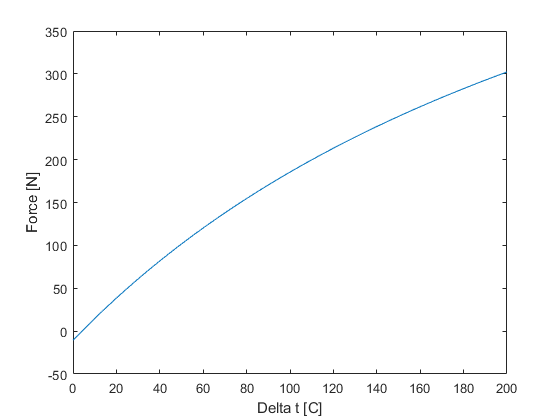

clearvars
d = 5;         %diamiter in m
r = d./2;
a = 4*pi().*(r.^2);         %surface area

p = 0.5;    %payload mass in kg
wpa = 0.0075;                %kg/m^2 mass per area
w_b = (a.*(wpa))+p;         % mass of balloon and payload

V = (4/3)*pi()*(r.^3);         % volume of balloon
roh_c = 1.204; % inital density of air
% Tc = 20;  %outside temp
% Tb = 25; %temp in balloon
dt = linspace(0,200);
beta = 0.0034; %1/c 

roh_b = roh_c./(1+beta.*(dt)); % density in balloon

g_c = 9.81;
Fl = V.*(roh_c-roh_b).*(g_c); %lift force
Fg = (w_b*(g_c))*(dt.^0);
F = Fl-Fg; %total force

figure(2)
clf;
plot(dt,F)
ylabel('Force [N]')
xlabel('Delta t [C]')

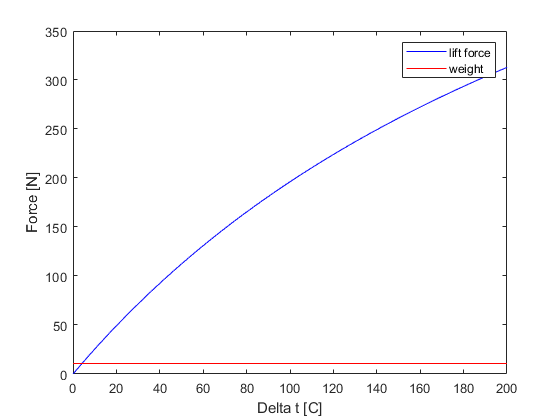


figure(3)
clf;
plot(dt,Fl,'b')
hold on
plot(dt,Fg,'r')
ylabel('Force [N]')
xlabel('Delta t [C]')
legend('lift force','weight')